# Distributed Coding Live Script - Single Trial All Neurons

## Setup

### MatNWB

Start by setting up your MATLAB workspace. The code below clones the MatNWB repo to the current directory and adds the folder ontaining the MatNWB package to the MATLAB search path. MatNWB works by automatically creating API classes based on a defined schema. Running the generateCore() function generates these classes for the lastest schema version.

!git clone https://github.com/NeurodataWithoutBorders/matnwb.git
cd ../matnwb
addpath(genpath(pwd));
generateCore();

### DANDIset

Download the relevant [DANDIset](https://dandiarchive.org/dandiset/000017/draft)

## Load in file

% path to file, change to desired file
DANDIset_folder = '~/DANDIsets/000017/';
filepath = [DANDIset_folder 'sub-Moniz/sub-Moniz_ses-20170515T120000.nwb'];
% read in file
nwb_file = nwbRead(filepath);
% display number of trials
ntrials = length(nwb_file.intervals_trials.start_time.data(:));
fprintf('Total trials: %d\n', ntrials)

Total trials: 247


## Plot trial details and response

% Select trial
trial = 10;

% print trial info
info = getTrialInfo(nwb_file, trial);
   
fprintf('Stimulus Contrast Left: %.02f || Right: %.02f\n', ...
    info.stim_contrast_left, ...
    info.stim_contrast_right)

Stimulus Contrast Left: 0.00 || Right: 0.50


fprintf('Animal Choice: %s \n',info.response_choice)

Animal Choice: Right 


fprintf('Feedback: %s \n',info.feedback_type)

Feedback: Reward 


fprintf('Reaction Time: %.02f seconds \n',info.reaction_time)

Reaction Time: 0.21 seconds 


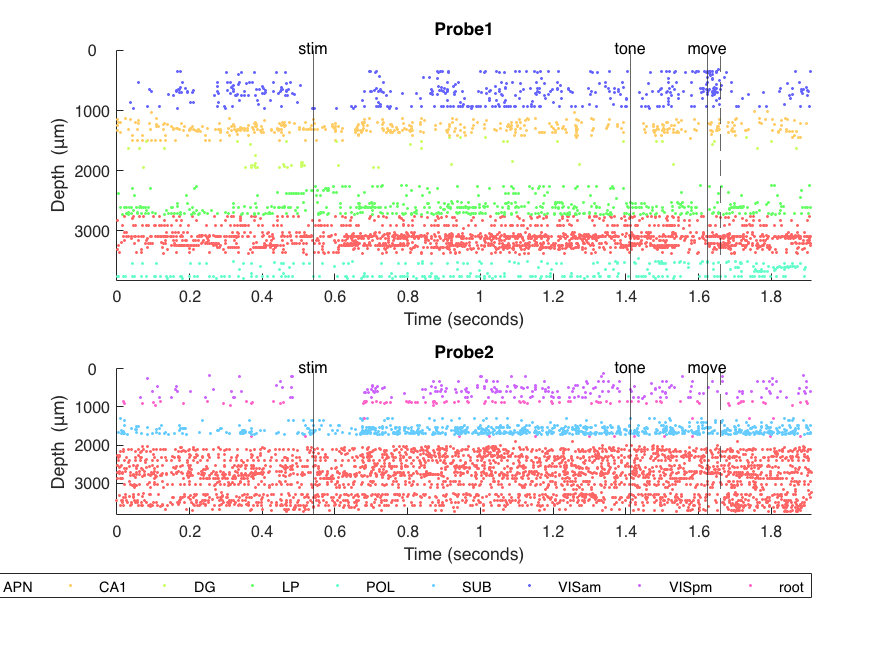

% output raster plot figure

plotRastersAllUnits(nwb_file, trial)